syms E I L M I B EA
L=0.1;                   %%m
E=750*1000;             %%pa
mu0=4*pi*10^-7;
Br=1.0;                    %T
M=Br/mu0         %%A/m

M = 7.9577e+05

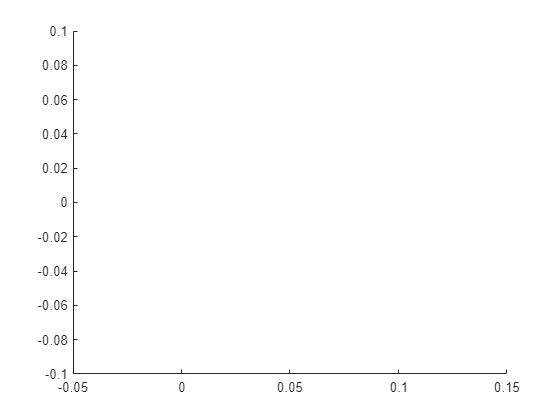

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.004*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능



syms A A10 A20 Alpha

figure
hold on
xlim([-0.5*L,1.5*L])
ylim([-L,L])

MarkerSize = 1

MarkerSize = 1


H=30000;
L1=0.05;

for  thetaB2=  10:10:160

thetaB2 =     10
    20
    30
    40
    50
    60
    70
    80
    90
   100


            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-(L-L1)];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);


실현불가능점으로 수렴되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작지만 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되지 않기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

내점법 실현가능성 모드를 활성화해 보십시오.



x = 1.0e-03 *

    0.1167    0.3500


       
end